format shortg
clear all

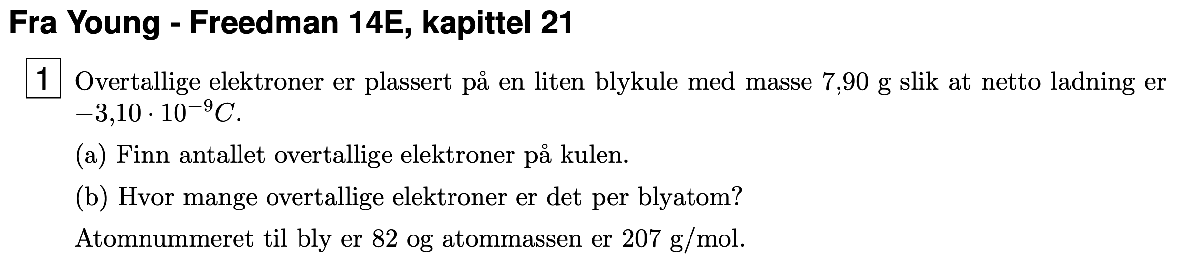

m =  7.90 * 10^-3; % kg
q = -3.10 * 10^-9; % C

(a)

antall_elektroner = abs(q/e);
signif(antall_elektroner, 3)

ans =      1.93e+10


(b)

mm_bly = 207 * 10^-3; %kg/mol
antall_blyatomer = mol*(m/mm_bly);
elektroner_per_blyatom = antall_elektroner/antall_blyatomer;
signif(elektroner_per_blyatom, 3)

ans =      8.42e-13


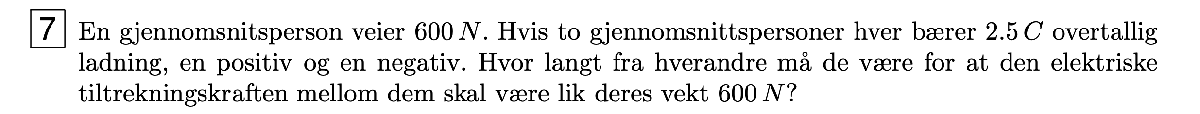

vekt_i_kilo = signif(Newton2(600, 0, g), 3)

vekt_i_kilo =          61.2


F = 600; % N
q = 2.5; % C
r = KraftMellomPunktladninger(F, q, q, 0);
signif(r, 3)

ans =         9680


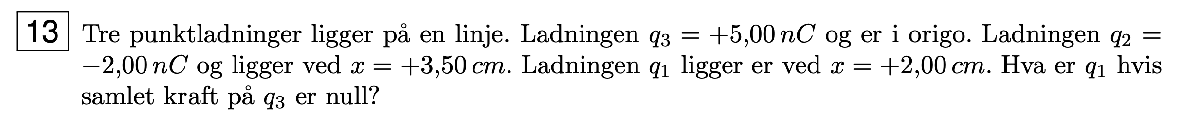

q3 =  5.00 * 10^-9; % C
pq3 = 0.00 * 10^-2; % m
q2 = -2.00 * 10^-9; % C
pq2 = 3.50 * 10^-2; % m
pq1 = 2.00 * 10^-2; % m

Samlet kraft på $q_3$ vil være null dersom kraften fra $q_1 \;\mathrm{og}\;q_2$ er like stor i punktet til $q_3$

Altsp når: $F_{\mathrm{q13}} =F_{\mathrm{q23}}$

F_q23 = KraftMellomPunktladninger(0, q2, q3, (pq2-pq3));
q1 = KraftMellomPunktladninger(F_q23, 0, q3, (pq1-pq3));
signif(q1, 3)

ans =      6.53e-10


Siden $q_1$ må kansellere kraften må de to ha forskjellig ladning, altså siden $q_2$ er negativ, må $q_1$være positiv for å nøytralisere kraften fra $q_2$

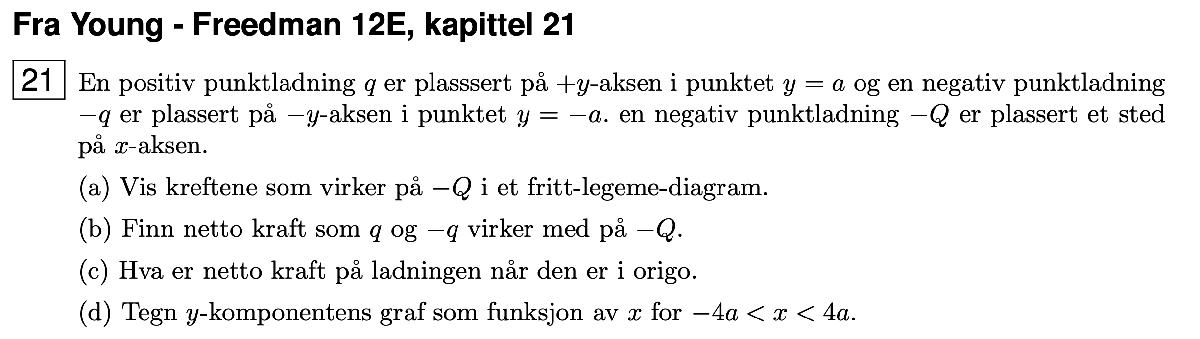

(a)

Summen av krefter på -Q vil være rett opover ettersom den negative ladningen i $+a$ vil trekke den mot seg like mye som ladningen i $-a$ vil skyve den fra seg, horistant blir kreftene altså 0, men kraften oppover adderes.

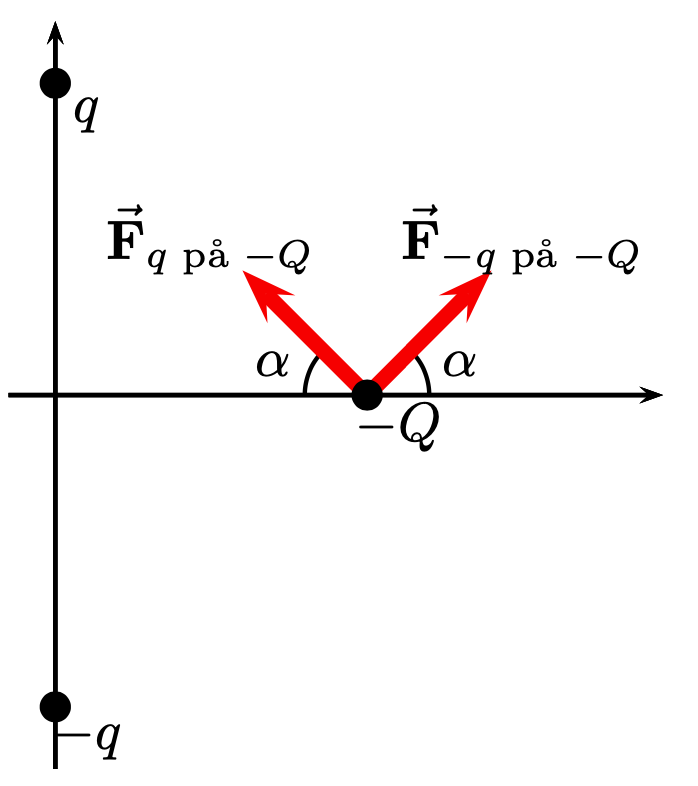

(b)

netto kraft blir:

avstanden $r\;$fra $Q\;\textrm{til}\;q\;\textrm{og}-q$ finner vi med pytagoras:


$$r^2 ={\left(\pm a\right)}^2 +x^2$$



$$F=\left(k*\frac{\left|-Q*-q\right|}{{-a}^2 +x^2 }\right)+\left(k*\frac{\left|-Q*q\right|}{a^2 +x^2 }\right)=2k*\frac{\mathrm{Qq}}{a^2 +x^2 }$$
 

(c)

$F=2k*\frac{\mathrm{Qq}}{r^2 }$ og i origo vil avtanden r, være a


$$F=2k*\frac{\mathrm{Qq}}{a^2 }$$


(d)

ser ut som en normalfordeling, høyest når x=0, og lavest ved endepunktene.

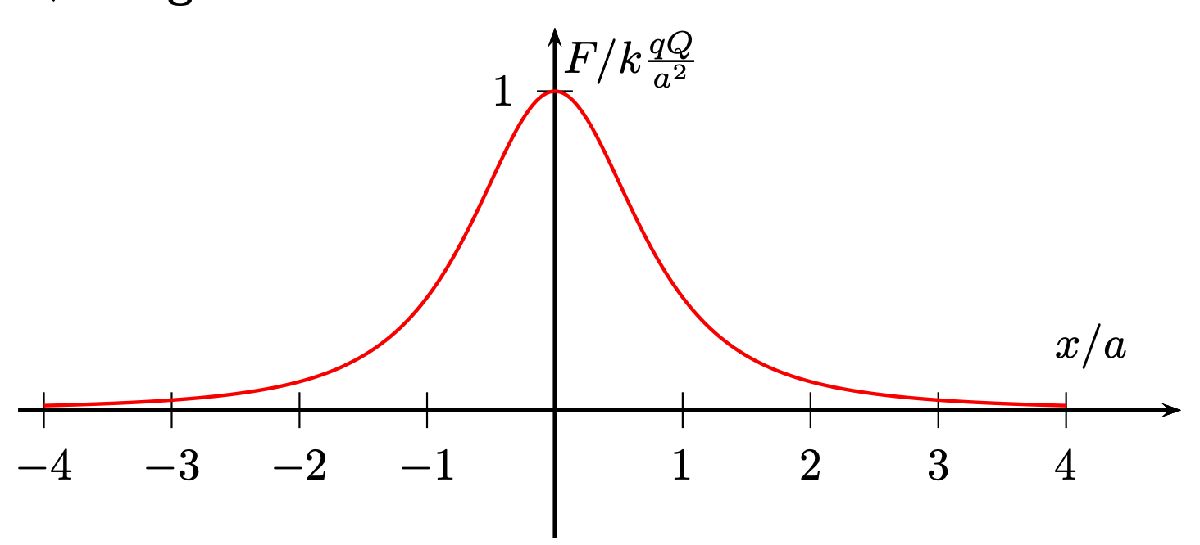

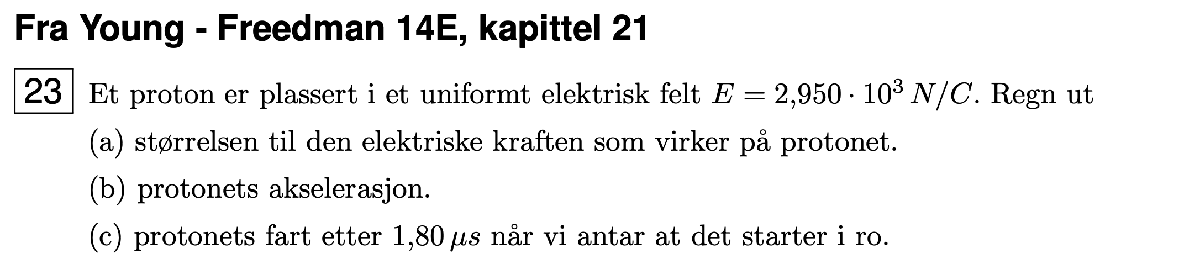

E = 2.950 * 10^3; % N/C

(a)

F = ElektriskKraft(0,e,E);
signif(F, 3)

ans =      4.73e-16


(b)

a = Newton2(F, m_p, 0);
signif(a, 3)

ans =      2.83e+11


(c)

t = 1.80 * 10^-6; % s
v = a*t;
signif(v, 3)

ans =       509000


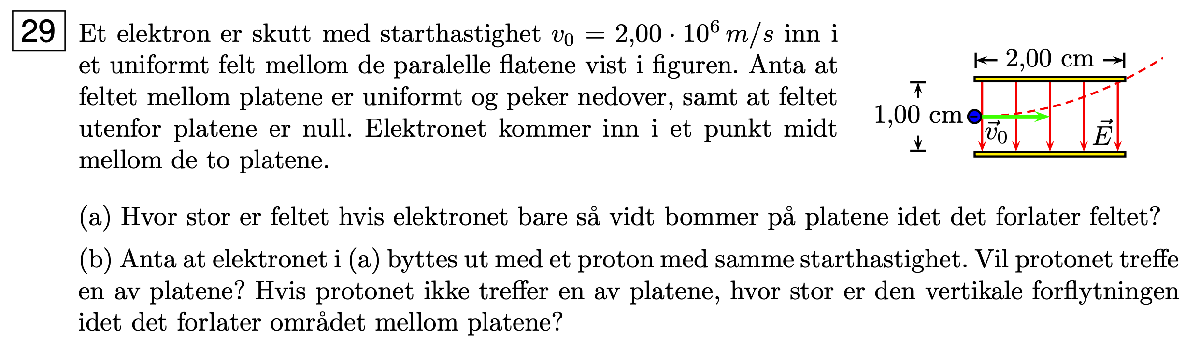

v_0 = 2.00 * 10^6; % m/s
d = 1.00/2 * 10^-2; % m
l = 2.00 * 10^-2; % m

(a)

t = KonstantFart(l,0,v_0,0);
a = KonstantAkselerasjon(d, 0, 0, t, 0);
F = Newton2(0, m_e, a);
E = ElektriskKraft(F, -e, 0);
signif(-E, 3)

ans =    569


Svaret er negativt ettersom elektronet går mot feltet.

(b)

F = ElektriskKraft(0, e, E);
a = Newton2(F, m_p, 0);
d = KonstantAkselerasjon(0,0,0,t,a);
signif(d, 3)

ans =     -2.72e-06


Svaret er negativt fordi protonet går motsatt vei av elektronet, altså er avtsanden nedover i retningen til feltet, istedenfor oppover og mot feltet.

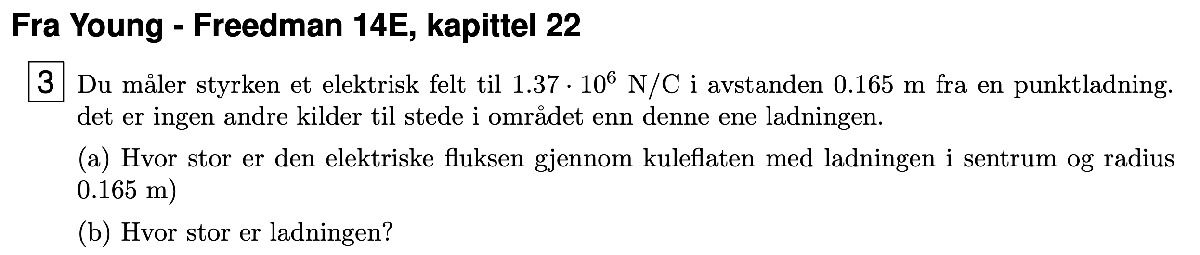

E = 1.37 * 10^6; % N/C
r = 0.165; % m

(a)

Siden det er en kule med ladning i sentrum går det elektriske feltet vinkelrett gjennom flaten til kulen:


$$\phi =E*A$$


fluks = E * ArealKule(r);
signif(fluks, 3)

ans =       469000


(b)

q = ElektriskFeltstyrkeFraPunktladning(E, 0, r)

q =      4.15e-06


Eller: Gauss-lov: $\phi_E =\frac{Q_{\mathrm{indre}} }{\varepsilon_0 }\Rightarrow Q_{\mathrm{indre}} =\phi_E *\varepsilon_0$

q = fluks * e_0

q =      4.15e-06


r = 20.0 * 10^-2; % m 
E = 1170; % N/C

A = ArealKule(r);
fluks = E * A;
q = fluks * e_0;
n = signif(q/e, 3)

n =      3.25e+10


q = ElektriskFeltstyrkeFraPunktladning(E,0,r);
n = signif(q/e, 3)

n =      3.25e+10


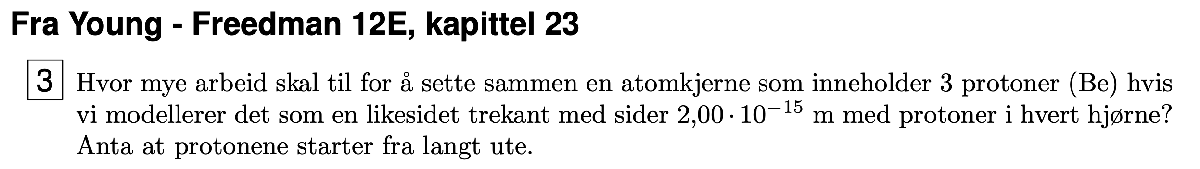

r = 2.00 * 10^-15; % m

Energien det vilt a å flytte protoenne hit, vil være lik den potensielle energien de har når de er plassert der:

Det er tre par med ladninger $1+2,\;2+3\;\mathrm{og}\;1+3$ da får vi:

U = 3 * PotensiellEnergiMellomPunktladninger(0,e,e,r); 
signif(U, 3) % Joule

ans =      3.46e-13


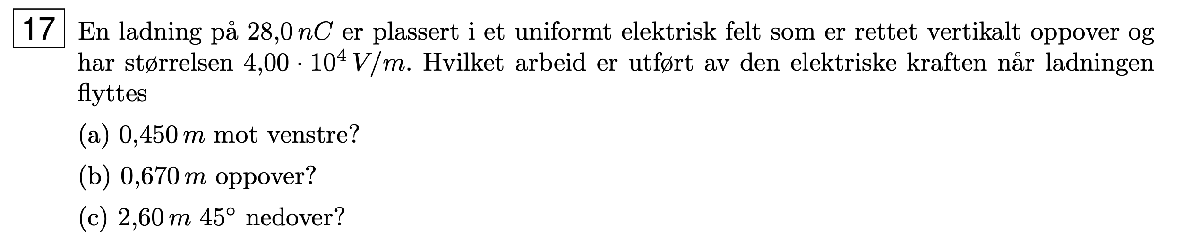

q = 28.0 * 10^-9; % C
E = 4.00 *10^4; % V/m

(a)

Siden vi beveger oss 90 grader på retningen til det elektriske feltet, gjør ikke feltet noe arbeid ettersom det er ingen endring i retnigne feltet presser.

s = 0.450; % meter
F = ElektriskKraft(0,q,E) * cosd(90)

F =      0


(b)

Vi beveger oss parallelt med feltet:

s = 0.670; % meter
F = ElektriskKraft(0,q,E) * cosd(0);
W = F*s;
signif(W, 3)

ans =       0.00075


(c)

s = 2.60; % meter
F = ElektriskKraft(0,q,E) * cosd(180-45);
W = F*s;
signif(W, 3)

ans =      -0.00206


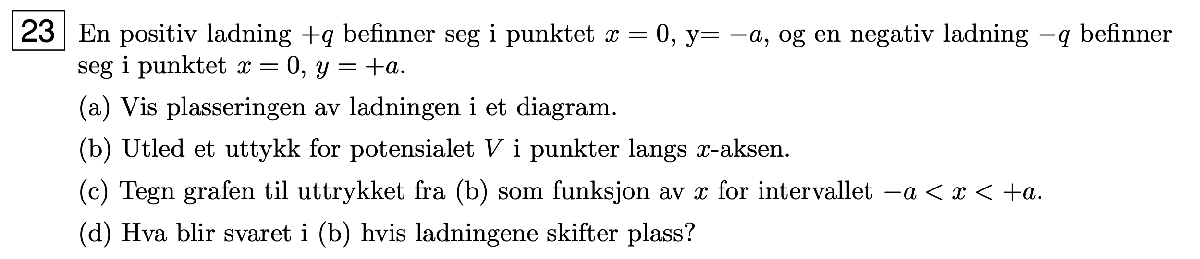

(a)

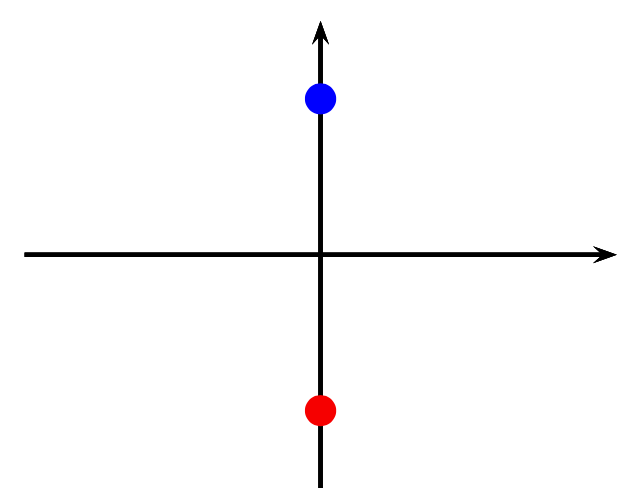

(b)


$$V=k*\frac{+q}{{-a}^2 +x^2 }+k*\frac{-q}{a^2 +x^2 }=\left(\frac{\mathrm{kq}}{a^2 +x^2 }\right)-\left(\frac{\mathrm{kq}}{a^2 +x^2 }\right)=0$$


(c)


$$y=0$$
    

(d)

0

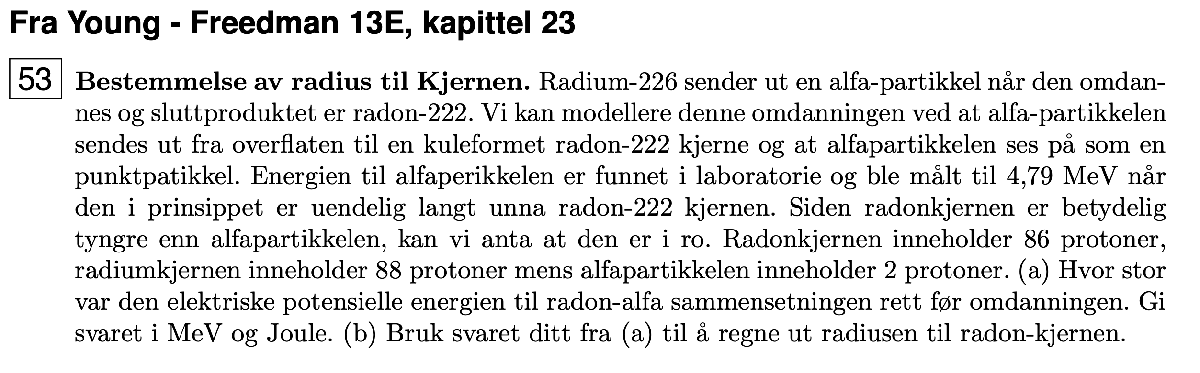

E_alpha = 4.79 * 10^6; % eV

(a)

Når alphapartikkelen er uendelig langt unna er all energien kinetisk energi, og vi vet at før alphapartikkelen ble sendt var den kinetiske energien 0. Dette betyr at den potensielle energien før utsendelsen må være lik den kinetiske energien etterpå:

Altså:

U = E_alpha * e; % Joule

(b)

r = PotensiellEnergiMellomPunktladninger(U, 2*e, 86*e, 0);
signif(r, 3) % m

ans =      5.17e-14
